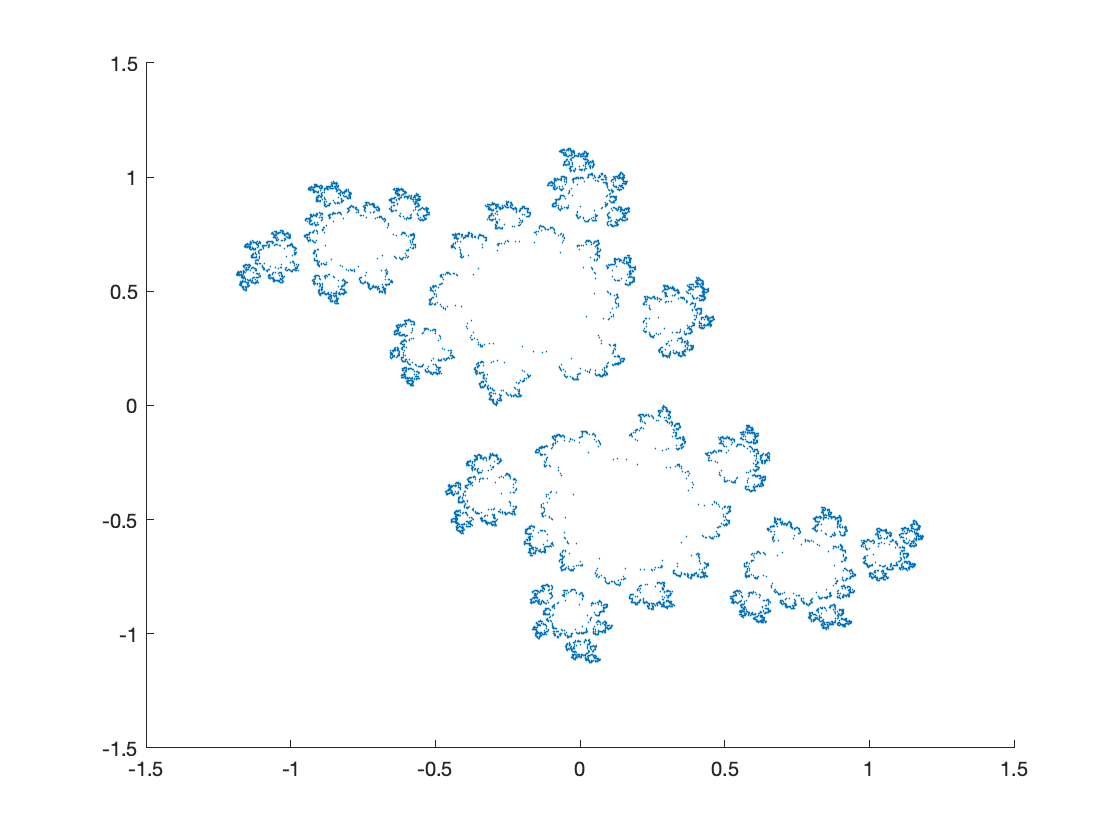

juliamodified(0.08 + 0.66i, 20, 1000)

Plots the julia set for any given complex value for c at a greater level of detail than juliasimple.

function output = juliamodified(c, depth, res)
    
    f = @(z) sqrt(z - c);
    newPoints = [1];
    pointsSoFar = [];

    for j = 1:depth
        val = f(newPoints);
        temp = [val; abs(val - newPoints); abs(-val - newPoints)];
        newPoints = [];
        for k = 1:length(val)
            if temp(2, k) > (1/res)
                newPoints = [newPoints val(k)];
            else
                pointsSoFar = [pointsSoFar val(k)];
            end
            if temp(3, k) > (1/res)
                newPoints = [newPoints -val(k)];
            else
                pointsSoFar = [pointsSoFar -val(k)];
            end
        end
    end
    
    pointsSoFar = [pointsSoFar newPoints];

    scatter(real(pointsSoFar), imag(pointsSoFar), 1, 'filled')

end